# Aero 2: Rotor Step Response Modelling

Step response modelling, also known as the *bump test*, is a simple test based on the step response of a stable system. A step input is given to the system and its response is recorded. The response of a first-order system can be described by the following transfer function:


$$\frac{Y(s)}{U(s)} = \frac{K}{\tau s + 1}$$


where $K
$is the known as the steady-state, or DC gain, and $\tau
$ is the time constant. The step response shown below is generated using this transfer function with $K = 5$ rad/s/V and $\tau = 0.05$ s.

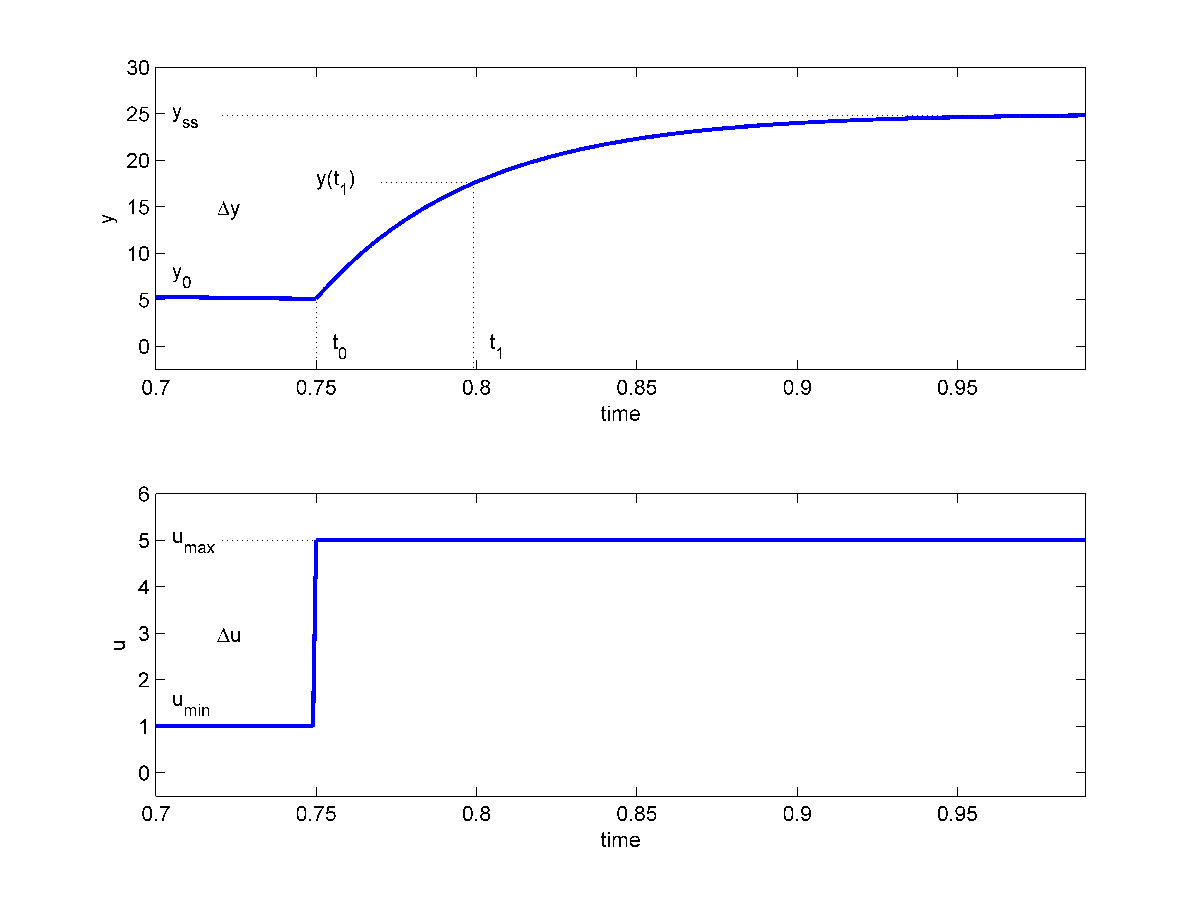

The step input begins at time $t_0
$. The input signal has a minimum value of $u_{min}
$ and a maximum value of $u_{max}
$. The resulting output signal is initially at $y_0
$. Once the step is applied, the output tries to follow it and eventually settles at its steady-state value $y_{ss}
$. The steady-state gain of the system can be found from its response using the input and output signals: 


$$K = \frac{\Delta y}{\Delta u}
$$


where $\Delta y = y_{ss} - y_0$ and $\Delta u = u_{max} -u_{min}$. The time constant of a system, $\tau
$, is defined as the time is takes the output of system to reach $1-e^{-1}=63.2$% of its steady-state value from the initial step time, $t_0$. The point where the output reaches 63.2% of its steady-state value can be defined


$$y(t_1) = 0.632 \Delta y + y_0.$$


where


$$t_1 = t_0 + \tau$$


The time $t_1
$ that corresponds to $y(t_1)$ can be found from the response data shown in the step response figure to obtain the model time constant


$$\tau = t_1 - t_0
$$


See the *Concept Review *document for more lab background.S

## Lab Procedure

### Measure Rotor Speed

Open the `q_aero2_rotor_step `Simulink model. 

% Load Simulink model
open("q_aero2_rotor_step.slx");

Build and run the model in QUARC by click on the *Monitor & Tune *button in Simulink. This will apply a 10V step to the rotor and measure the corresponding rotor speed using the digital tachometer. 

**Student Exercise**: Plot the response in MATLAB figure. The scopes are configured to save the measured rotor speed and motor voltage to the MATLAB workspace in the variables `DataRotorSpeed `and `DataRotorVm`, where the `DataRotorVm.time` is the time vector, `DataRotorSpeed.signals.values` is the measured speed, `DataRotorVm.signals.values` is the applied voltage. 

% Load measured data from past run. Uncomment to use new data.
load('DataRotorStep.mat');
% load data into variables
t = DataRotorVm.time; 
u = DataRotorVm.signals.values;
ymeas = DataRotorSpeed.signals.values;
% plot
% Student: enter code to plot response

### Find Rotor Transfer Function

Find the transfer function of the voltage to rotor speed and validate against measured data.

**Student Exercise**: Find the steady-state gain.

% Student: Enter the amplitude of the step input
du = ;
% Student: Enter the difference between the final steady-state and initial output
dy = ;
K = dy/du

**Student Exercise**: Find the time constant. 

% initial speed (rad/s)
y0 = ;
% Response at first decay time (rad/s)
y_t1 = (1-exp(-1))*dy + y0;
% Step start time (s)
t0 = 1;
% Find time of first decay (s)
t1 = ;
% Experimentally derived time constant (s)
tau = t1 - t0

**Student Exercise**: Enter rotor transfer function model. Hint: Use the `tf `MATLAB command.

RotorTF = 

### Model Validation

Open the `q_aero2_rotor_model_val `Simulink model. 

% Load Simulink model
open("q_aero2_rotor_model_val.slx");

Build and run the model in QUARC by clicking on the *Monitor & Tune *button in Simulink. This will apply a 10V step to the Aero 2 rotor hardware and the model. The rotor speed measured from the digital tachometer on the actual Aero 2 and the simulated rotor speed from the model are displayed in the same Scope.

Plot the response in MATLAB figure. The scopes are configured to save the measured rotor speed and motor voltage to the MATLAB workspace in the variables `DataRotorSpeed `and `DataRotorVm`, where the `DataRotorVm.time` is the time vector, `DataRotorSpeed.signals.values` is the measured speed, `DataRotorVm.signals.values` is the applied voltage. 

% Load measured data from past run. Uncomment to use new data.
load('DataRotorModelVal.mat');
% load data into variables
t = DataRotorModelVal_Vm.time; 
u = DataRotorModelVal_Vm.signals.values;
ymeas = DataRotorModelVal_Speed.signals(1).values;
ysim = DataRotorModelVal_Speed.signals(2).values;
%
% Student: enter code to plot response